# Load Cell Parsing

## Import Data

clear; clc; close all;

HEIGHT = 2;
TRIAL = 3;

% Combine them into a single string for the switch
combination = sprintf('H%d_T%d', HEIGHT, TRIAL);

switch combination
    case 'H0_T0'
        disp('Processing Test Data...');
        confirmation_array = [2 3 5 7 8]; % for test data
        filename = 'load_cell_test_data.csv';
        cal_domain = 1:100;

    case 'H1_T1'
        disp('Processing Height 1, Trial 1...');
        % Add specific peak detection parameters for this trial
        confirmation_array = [1:7 9:12]; %n1 trial 1
        filename = 'manual_n1_trial1.csv';
        cal_domain = 1:10000;
        
    case 'H2_T1' % You can group trials together
        disp('Processing Height 50, Trial 1...');
        confirmation_array = 1; % for n2 trial 1
        filename = 'manual_n2_trial1.csv';
        cal_domain = 2000:12000;
        
    case 'H2_T2' % You can group trials together
        disp('Processing Height 50, Trial 2...');
        confirmation_array = [2 3 4 5]; % for n2 trial 2
        filename = 'manual_n2_trial2.csv';
        cal_domain = 2000:8000;
    
    case 'H2_T3'
        disp('Processing Height 2, Trial 3...');
        confirmation_array = 1:10; % for n2 trial 3
        filename = 'manual_n2_trial3.csv';
        cal_domain = 2000:12000;

    case 'H3_T1'
        disp('Processing Height 3, Trial 1...');
        confirmation_array = 6; % for n3 trial 1
        filename = 'manual_n3_trial1.csv';
        cal_domain = 2000:12000;

    case 'H3_T2'
        disp('Processing Height 3, Trial 2...');
        confirmation_array = [1 2 3 4 5 6 7 8 9]; % for n3 trial 2
        filename = 'manual_n3_trial2.csv';
        cal_domain = 2000:12000;

    case 'H3_T3'
        disp('Processing Height 3, Trial 3...');
        confirmation_array = [1 2 3 4 5 6 7 8]; % for n3 trial 3
        filename = 'manual_n3_trial3.csv';
        cal_domain = 4000:13000;

    case 'H3_T4'
        disp('Processing Height 3, Trial 4...');
        confirmation_array = [1 2 3 4 5 6 7 8 9 10]; % for n3 trial 4
        filename = 'manual_n3_trial4.csv';
        cal_domain = 2000:12000;
        
    otherwise
        fprintf('Combination %s not recognized.\n', combination);
end

Processing Height 2, Trial 3...



opts = detectImportOptions(filename);
data = readtable(filename, opts);

## Format Data

raw_time = data.Timestamp; % e.g., 13025702930
force_data = data.Fz;   % The load cell reading
time = (raw_time - raw_time(1)) ./ 1e6;
force = -1.*force_data;
force = force - force(1);

[~, uniqueIdx] = unique(time, 'stable');

% re-indexing the table to keep only unique rows
time = time(uniqueIdx, :);
force = force(uniqueIdx, :);

## Search for Peaks

minHeight = 5; %Newtons
nominal_sample_fq = 1000; % 1,000 Hz
minPeakDistance = 1.*nominal_sample_fq; % seconds
[pks, locs] = findpeaks(force, 'MinPeakHeight', minHeight, 'MinPeakDistance', minPeakDistance);
peak_times = time(locs);

%confirmation_array = 1:length(pks); %default
confirmed_peaks = pks(confirmation_array);
confirmed_peak_times = peak_times(confirmation_array);

% Display peaks
fprintf('Found %d peaks in the dataset.\n', length(confirmed_peaks));

Found 10 peaks in the dataset.


confirmed_peak_table = table(confirmed_peak_times, confirmed_peaks, 'VariableNames', {'Time_s', 'Force_Value'});
disp(confirmed_peak_table);

    Time_s    Force_Value
    ______    ___________

    24.558      21.735   
    34.746      17.978   
    46.304      17.516   
    68.306      16.344   
    84.693      16.833   
    108.98      18.089   
    125.77      18.353   
    136.72       17.34   
    152.33      15.438   
    174.63       20.69   



avg_peak = mean(confirmed_peaks)

avg_peak = 18.0316

## Check Sampling Rate

instant_period = ones(length(time) - 1,1);
for i = 1:length(time) - 1
    instant_period(i) = time(i+1) - time(i);
end
instant_fq = 1./instant_period;
max(instant_fq)

ans = 1.0000e+06

### Sampling Statistics:

smoothed_fq = instant_fq(instant_fq < 2000);
avg_fq = mean(smoothed_fq)

avg_fq = 994.2455

max_fq = max(smoothed_fq)

max_fq = 1.9881e+03

min_fq = min(smoothed_fq)

min_fq = 5.0760

stdev_fq = std(smoothed_fq)

stdev_fq = 61.9068

## Graph Peaks

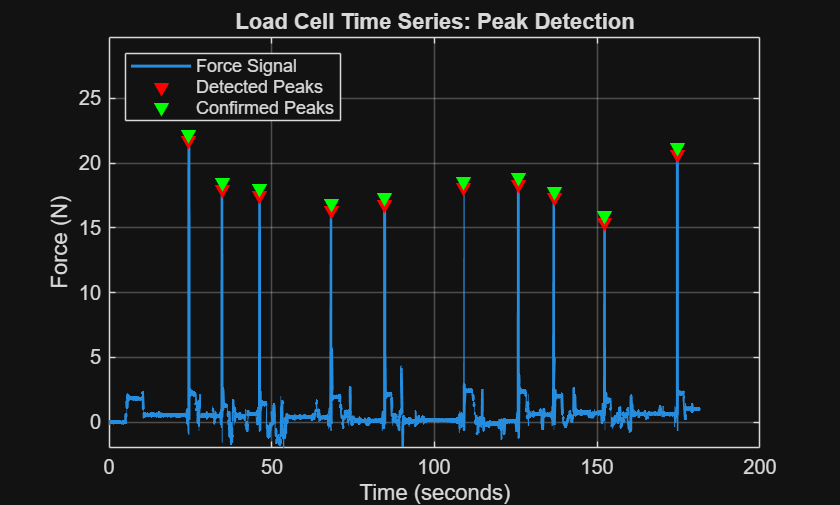

fig(1) = figure;
plot(time, force, 'LineWidth', 1.5);
hold on;
plot(peak_times, pks, 'rv', 'MarkerFaceColor', 'r'); % Red triangles at peaks
plot(confirmed_peak_times, confirmed_peaks + 0.5, 'gv', 'MarkerFaceColor', 'g'); % Red triangles at peaks
grid on;
hold off;
xlabel('Time (seconds)');
ylabel('Force (N)');
ylim([-2 max(force)+8]);
title('Load Cell Time Series: Peak Detection');
legend('Force Signal', 'Detected Peaks', 'Confirmed Peaks', 'Location', 'northwest');

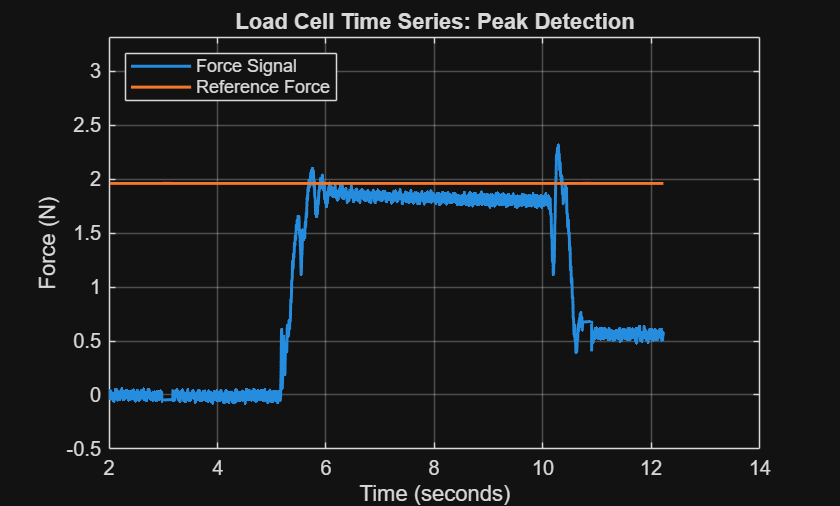

fig(6) = figure;
plot(time(cal_domain), force(cal_domain), 'LineWidth', 1.5);
hold on;
plot(time(cal_domain), 0.2.*9.81.*ones(1,length(cal_domain)), 'LineWidth', 1.5);
grid on;
hold off;
xlabel('Time (seconds)');
ylabel('Force (N)');
ylim([-0.5 max(force(cal_domain))+1]);
title('Load Cell Time Series: Peak Detection');
legend('Force Signal', 'Reference Force', 'Location', 'northwest');

## Graph Frequency Histogram

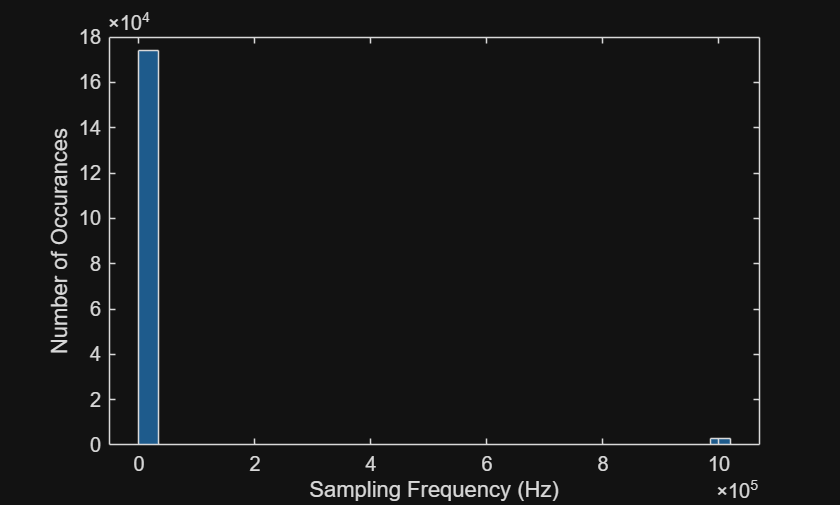

fig(2) = figure;
freq_label = "Sampling Frequency (Hz)";
occur_label = "Number of Occurances";
histogram(instant_fq, 30);
xlabel(freq_label);
ylabel(occur_label);

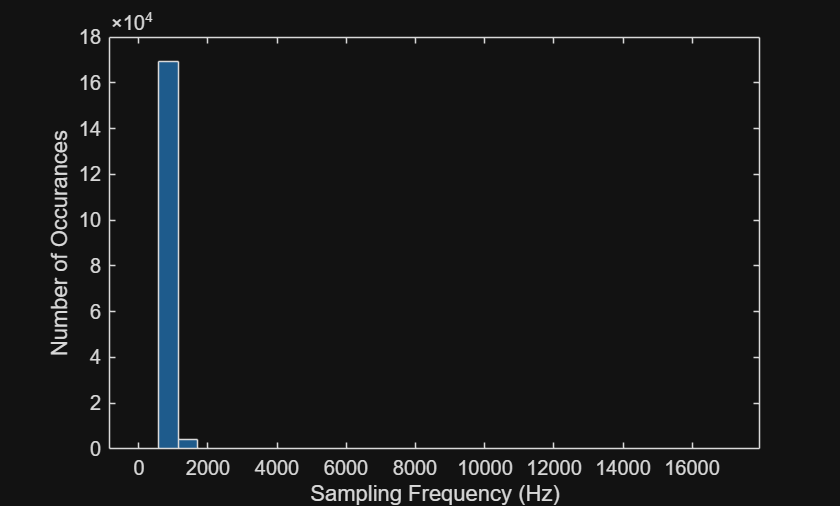

fig(3) = figure;
fq_low_pass = instant_fq(instant_fq < 20000);
histogram(fq_low_pass, 30);
xlabel(freq_label);
ylabel(occur_label);

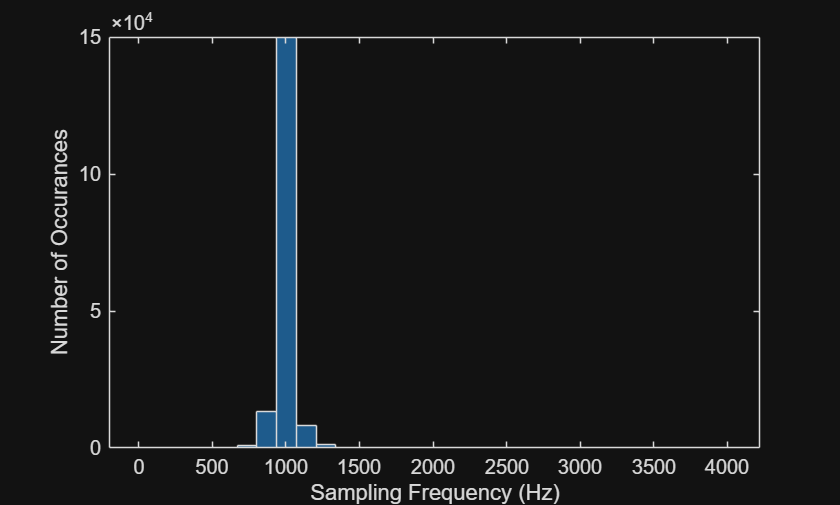

fig(4) = figure;
fq_lower_pass = instant_fq(instant_fq < 4000);
histogram(fq_lower_pass, 30);
xlabel(freq_label);
ylabel(occur_label);

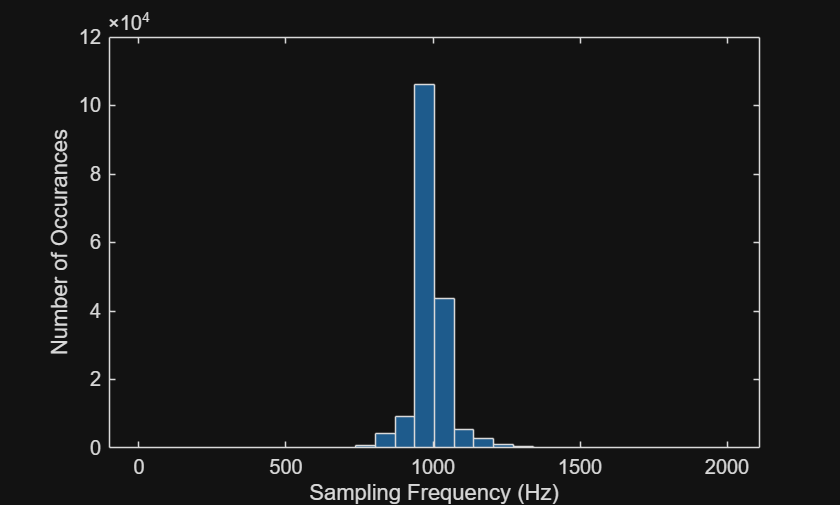

fig(5) = figure;
fq_lowest_pass = instant_fq(instant_fq < 2000);
histogram(fq_lowest_pass, 30);
xlabel(freq_label);
ylabel(occur_label);